PARÁMETROS

% Control

shi=0.4; % Minimum damping coefficient.
wn=20; % Natural frequency. 

% Sistema

J=6; % Inertia.
Ra=0.3; % Resistencia de la armadura del motor.
kt=0.5; %Constante de conversión tensión-par.
kv=0.5; %Constante de fuerza contraelectromotriz.

% Realimentaciones

kTP=1; %Ganancia en la realimentación de la posición.
kTV=1; %Ganancia en la realimentación de la velocidad.

CONSTANTES CONTROLADOR

Kv=(2*shi*wn*kv)/kTV; % Ganancia de velocidad.

Kp=(wn^2*kv)/(kTP*Kv); % Ganancia de posición.

Tv=(Ra*J)/(kv*kt); % Cero del controlador.

ESPACIO DE ESTADOS

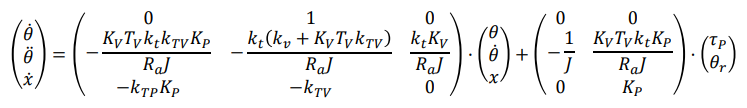

A=[0 1 0;-Kv*Tv*kt*kTV*Kp/Ra/J -(kv*kt+Kv*Tv*kt*kTV)/Ra/J kt*Kv/Ra/J;-kTP*Kp -kTV 0];
B=[0 0;-1/J Kv*Tv*kt*Kp/Ra/J;0 Kp];
C=[1 0 0;0 1 0]; % Salida = [theta, theta_dot]
D=[0 0; 0 0];

SIMULACIÓN STEP

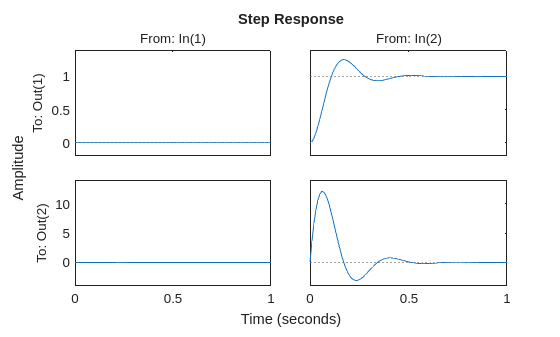

G=ss(A,B,C,D);
step(G,0.6);

SIMULACIÓN TRAYECTORIA

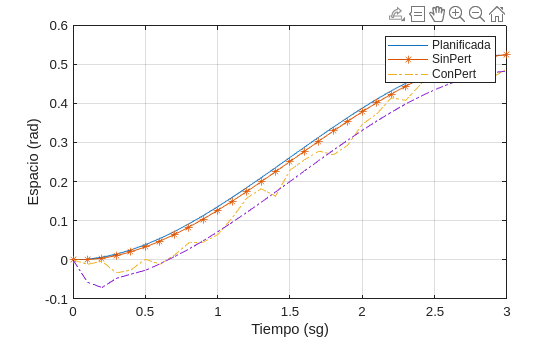

% Parámetros
q0 = [0 , 0];   % 
qf = [pi/6 , 0];

tf = 3;
res = 0.1;

% Entradas
[T,W]=cubica([0,0],[pi/6,0],3,0.1);   % Tiempos y Trayectoria de cada Tiempo

Upert1 =[150*rand(size(W,2),1),W(1,:)'];    % tau_p = 0 y \theta_r = trayectoria
Upert2 =[150*ones(size(W,2),1),W(1,:)'];    % tau_p = 0 y \theta_r = trayectoria
U =[zeros(size(W,2),1),W(1,:)'];    % tau_p = 0 y \theta_r = trayectoria

% Simulación
[Y,T]=lsim(G,U,T);
[Ypert1,T]=lsim(G,Upert1,T);
[Ypert2,T]=lsim(G,Upert2,T);
plot(T,W(1,:),'-',T,Y(:,1)','-*',T,Ypert1(:,1)','-.',T,Ypert2(:,1)','-.')
xlabel('Tiempo (sg)');
ylabel('Espacio (rad)');
grid
legend('Planificada','SinPert','ConPert');

FUNCIONES

% GENERACIÓN DE TRAYECTORIAS CON POLINOMIO CÚBICO
function [T,W]=cubica(q0,qf,tf,res)
    % Generación de una trayectoria articular
    %mediante una función cúbica
    % desde q0(1) con velocidad q0(2) hasta qf(1) con
    %velocidad final qf(2) en
    % un tiempo tf.
    %
    % function [T,W]=cubica(q0,qf,tf,res)
    %
    % q0(1x2): Valor articular y velocidad inicial.
    % qf(1x2): Valor articular y velocidad final.
    % tf: Tiempo para recorrer la trayectoria.
    % res: Tiempo de muestreo de la trayectoria.
    %
    % T(1xn): Vector de tiempos.
    % W(3xn): Trayectoria articular generada.
    % Planificación: Definición del polinomio cúbico
    %y sus derivadas.

    p=zeros(1,4);
    p(4)=q0(1);
    p(3)=q0(2);
    p(2)=3/tf^2*(qf(1)-q0(1))-2/tf*q0(2)-1/tf*qf(2);
    p(1)=-2/tf^3*(qf(1)-q0(1))+1/tf^2*(qf(2)+q0(2));
    dp=polyder(p); ddp=polyder(dp);

    % Generación de la trayectoria
    T=0:res:tf;
    W=[polyval(p,T);polyval(dp,T);polyval(ddp,T)];
end